%% CCM–ARDUINO COMPARATOR (single tendon, 1-DoF)
% Mirrors your Arduino math for: A <deg>  -> steps,
% and also steps/turns -> predicted bend. Includes visualization.

clear; clc;

%% ---- PARAMETERS: match your firmware/hardware ----
L            = 0.116;          % robot length [m] (11.6 cm)
D_robot      = 0.017;          % robot diameter [m] (17 mm)
r_cable      = 0.5*(D_robot/2);% channel at mid-radius (4.25 mm)
r_spool      = 0.012/2;        % winding diameter 12 mm -> radius 6 mm
C_spool      = 2*pi*r_spool;   % circumference [m]

steps_per_rev_motor = 200;     % NEMA17 = 200 full steps/rev
microstep            = 1;      % << set to your jumper setting (1 for now)
STEPS_PER_REV        = steps_per_rev_motor * microstep;

CALX = 1.0;                    % firmware scale (if you use it); 1.0 now

% Sign convention: negative angle -> pull (shorten) on the active tendon at theta=0
% This matches your current Arduino setup where negative A winds in.
pull_is_negative = true;

%% ---- SELECT MODE ----
% 1) Simulate the Arduino A <deg> command:
mode = "from_angle";        % "from_angle" or "from_steps"

cmd_deg   = -100;           % put the exact A value you typed in Arduino (e.g., -200)
% 2) Or simulate from a step count (e.g., from logs):
cmd_steps = 3200;           % used if mode="from_steps" (example)
% cmd_steps = 250;

%% ---- CORE MAPPING (Arduino-equivalent) ----
angleDegToSteps = @(deg) round( ( (deg*pi/180) * r_cable / C_spool ) * STEPS_PER_REV * CALX );

stepsToAngleDeg = @(steps) ( (steps/(STEPS_PER_REV*CALX)) * (C_spool/r_cable) ) * (180/pi);

%% ---- Solve according to mode ----
if mode == "from_angle"
    psi_cmd_deg = cmd_deg;                        % “A <deg>” input as in Arduino
    steps       = angleDegToSteps(psi_cmd_deg);   % same rounding as firmware
    turns       = steps / STEPS_PER_REV;
    dL          = turns * C_spool;                % signed ΔL [m]
    % Signed CCM bend angle (ideal model):
    psi         = psi_cmd_deg * pi/180;           % rad (signed)
    source_txt  = sprintf('MODE: from_angle (A %g deg)', psi_cmd_deg);

elseif mode == "from_steps"
    steps       = cmd_steps;
    turns       = steps / STEPS_PER_REV;
    dL          = turns * C_spool;                % signed ΔL [m]
    % Invert to get signed angle as Arduino would:
    psi         = (stepsToAngleDeg(steps)) * pi/180;
    psi_cmd_deg = stepsToAngleDeg(steps);
    source_txt  = sprintf('MODE: from_steps (%d steps, %.4f turns)', steps, turns);

else
    error('Unknown mode.');
end

%% ---- Two interpretations to compare ----
% A) "Ideal CCM (signed)": the backbone is a circular arc with signed psi.
%    This is what pure math would say if you could bend both ways.
psi_signed = psi;
kappa_signed = psi_signed / L;        % curvature (signed) [1/m]
phi_signed   = 0;                     % bending plane (set to 0 for viz)

% B) "Single-tendon physical": one tendon can only PULL.
%    If command sign says "unwind", real curvature cannot go past straight in opposite direction.
%    We emulate that by taking curvature magnitude from PULL only.
if pull_is_negative
    % dL < 0 means pull; dL >=0 means pay out (no push)
    dL_pull = min(dL, 0);            % negative or zero
else
    dL_pull = max(dL, 0);            % positive or zero
end
kappa_physical = max(0, -dL_pull / (r_cable * L));   % ≥ 0
psi_physical   = kappa_physical * L;                  % ≥ 0
phi_physical   = 0;                                   % bends toward the active tendon

%% ---- Build shapes for both interpretations ----
s = linspace(0, L, 200);
if abs(kappa_signed) < 1e-9
    x_s = zeros(size(s));  z_s = s;         % y=0 in plane
else
    x_s = (1/kappa_signed) * (1 - cos(kappa_signed*s)) * cos(phi_signed);
    z_s = (1/kappa_signed) * sin(kappa_signed*s);
end

if abs(kappa_physical) < 1e-9
    x_p = zeros(size(s));  z_p = s;
else
    x_p = (1/kappa_physical) * (1 - cos(kappa_physical*s)) * cos(phi_physical);
    z_p = (1/kappa_physical) * sin(kappa_physical*s);
end

% Chord angles (base->tip line) are ~psi/2 for perfect arcs
alpha_signed   = atan2(x_s(end), z_s(end));           % rad
alpha_physical = atan2(x_p(end), z_p(end));           % rad

%% ---- Report ----
fprintf('\n%s\n', source_txt);


MODE: from_angle (A -100 deg)


fprintf('Robot: L=%.1f mm, D=%.1f mm, r_cable=%.2f mm\n', L*1e3, D_robot*1e3, r_cable*1e3);

Robot: L=116.0 mm, D=17.0 mm, r_cable=4.25 mm


fprintf('Spool: wind Ø=12 mm (r=%.1f mm), C=%.2f mm\n', r_spool*1e3, C_spool*1e3);

Spool: wind Ø=12 mm (r=6.0 mm), C=37.70 mm


fprintf('Motor: %d steps/rev, microstep=%d  => STEPS_PER_REV=%d\n', steps_per_rev_motor, microstep, STEPS_PER_REV);

Motor: 200 steps/rev, microstep=1  => STEPS_PER_REV=200


fprintf('CALX:  %.4f (steps scaling)\n', CALX);

CALX:  1.0000 (steps scaling)



fprintf('\nArduino-equivalent mapping:\n');


Arduino-equivalent mapping:


fprintf('  steps = %d (turns = %.5f),  ΔL = %.3f mm  (sign: %.0f=pull-is-negative)\n', ...
    steps, turns, dL*1e3, pull_is_negative);

  steps = -39 (turns = -0.19500),  ΔL = -7.351 mm  (sign: 1=pull-is-negative)



fprintf('\nIdeal CCM (signed):\n');


Ideal CCM (signed):


fprintf('  ψ_signed (tip tangent) = %.2f deg\n', rad2deg(psi_signed));

  ψ_signed (tip tangent) = -100.00 deg


fprintf('  α_signed (chord)       = %.2f deg (≈ ψ/2)\n', rad2deg(alpha_signed));

  α_signed (chord)       = -50.00 deg (≈ ψ/2)


fprintf('  Tip: x=%.2f mm, z=%.2f mm\n', x_s(end)*1e3, z_s(end)*1e3);

  Tip: x=-78.00 mm, z=65.45 mm



fprintf('\nSingle-tendon physical (pull-only):\n');


Single-tendon physical (pull-only):


fprintf('  ψ_physical (tip tangent) = %.2f deg\n', rad2deg(psi_physical));

  ψ_physical (tip tangent) = 99.11 deg


fprintf('  α_physical (chord)       = %.2f deg (≈ ψ/2)\n', rad2deg(alpha_physical));

  α_physical (chord)       = 49.55 deg (≈ ψ/2)


fprintf('  Tip: x=%.2f mm, z=%.2f mm\n', x_p(end)*1e3, z_p(end)*1e3);

  Tip: x=77.68 mm, z=66.22 mm


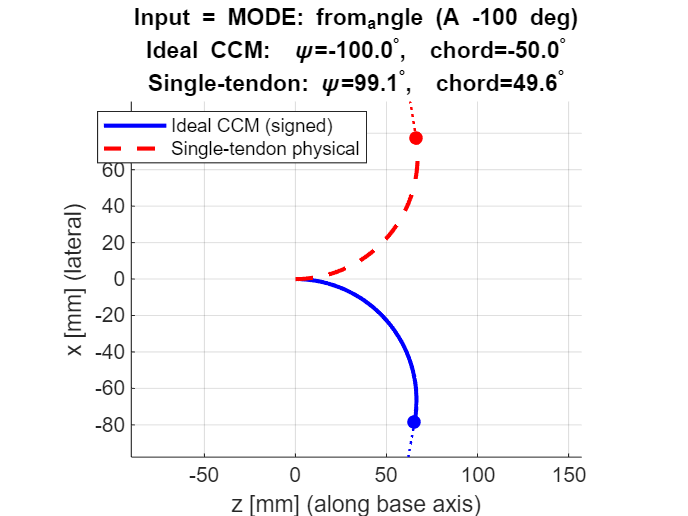


%% ---- Plot both on same axes for comparison ----
figure; clf; hold on; grid on; axis equal;
% plot z on x-axis and x on y-axis (bending plane)
plot(z_s*1e3, x_s*1e3, 'b-', 'LineWidth', 2);    % ideal signed CCM
plot(z_p*1e3, x_p*1e3, 'r--', 'LineWidth', 2);   % single-tendon physical
plot(z_s(end)*1e3, x_s(end)*1e3, 'bo', 'MarkerFaceColor','b');
plot(z_p(end)*1e3, x_p(end)*1e3, 'ro', 'MarkerFaceColor','r');

% draw tip tangents
scale = 20; % mm
tdir_s = [cos(psi_signed), sin(psi_signed)];    % [z,x]
tdir_p = [cos(psi_physical), sin(psi_physical)];
p2s = [z_s(end)*1e3, x_s(end)*1e3] + scale*tdir_s;
p2p = [z_p(end)*1e3, x_p(end)*1e3] + scale*tdir_p;
plot([z_s(end)*1e3 p2s(1)], [x_s(end)*1e3 p2s(2)], 'b:', 'LineWidth', 1.2);
plot([z_p(end)*1e3 p2p(1)], [x_p(end)*1e3 p2p(2)], 'r:', 'LineWidth', 1.2);

xlabel('z [mm] (along base axis)'); ylabel('x [mm] (lateral)');
title({sprintf('Input = %s', source_txt), ...
       sprintf('Ideal CCM:  \\psi=%.1f^\\circ,  chord=%.1f^\\circ', rad2deg(psi_signed), rad2deg(alpha_signed)), ...
       sprintf('Single-tendon: \\psi=%.1f^\\circ,  chord=%.1f^\\circ', rad2deg(psi_physical), rad2deg(alpha_physical))});
legend('Ideal CCM (signed)', 'Single-tendon physical', 'Location', 'Best');